# **STEP_03:  **Explore a simple cantilever - **IMPACT excitation test (EMA or SYSID)**

Let's get familiar with the Flexible Beam block in Simscape Multibody

- [https://www.mathworks.com/help/releases/R2026a/sm/ref/flexiblerectangularbeam.html](https://www.mathworks.com/help/releases/R2026a/sm/ref/flexiblerectangularbeam.html)

And what better way, than to model and VERIFY the behavior of a simple cantilever beam 

**Objectives:**

- Analyze the measurement data collected from the IMPACT test in step_02

- Computer **Frequency Response Functions** (FRFs)

- Extract the **Modal properties** from the FRFs

- **Compare** the extracted bending modes with those computed using Engineering beam Theory.

So here is the Cantilever system that we're going to focus on - and note the orientation of the **Inertial reference frame**.

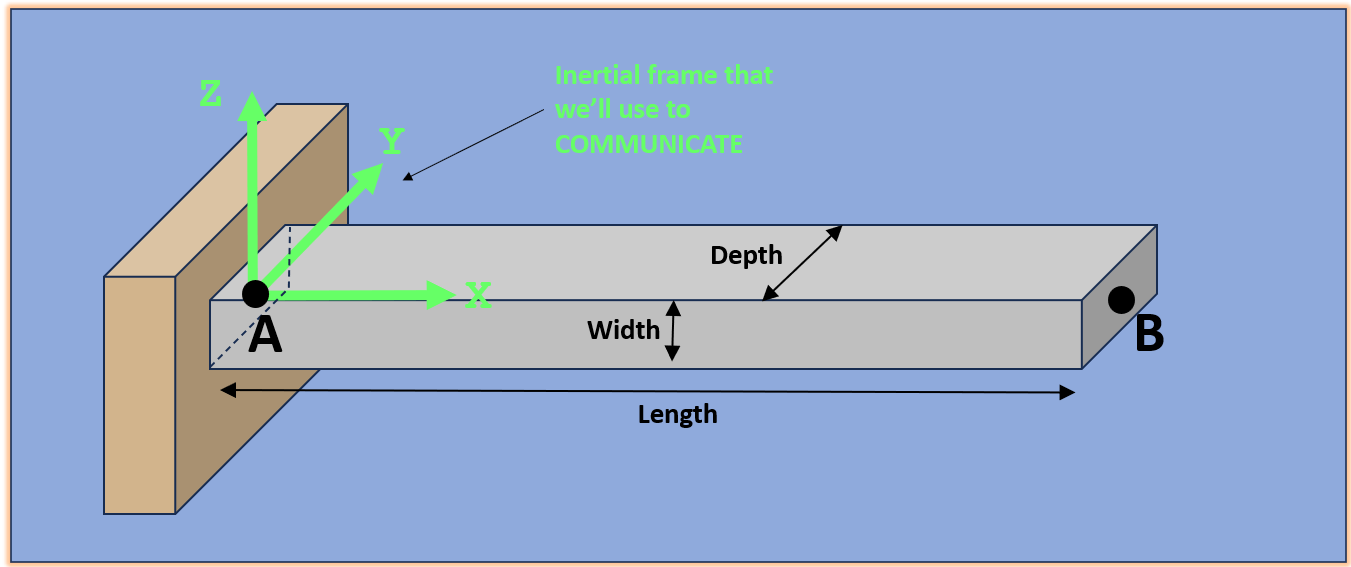

## Background:

Recall the parametric equation of a Frequency Response Function (FRF) of a Mechanical structure:

- 
$$\mathrm{FRF}=\;\left(\sum_{k=1}^N \left.\frac{R_k }{s-\lambda_k }+\;\frac{\bar{R_k } }{s-\bar{\lambda_k } }\right)\;\;\;+\;\;e\;\;+\;\;\;\;\frac{f}{s^2 }\right.$$
          

where we have:

- **MODAL poles**:       $\lambda_k \;\;\;=\;-\zeta_k \ldotp \omega_{n_k } \;\;\;+\;\;\;j\ldotp \omega_{n_k } \ldotp \sqrt{\;1\;-{\zeta_k }^2 \;}$

- **RESIDUES**:            $R$

So ? - So in this script we'll 

- Convert the measured times series data into **Frequency Response Functions **(FRFs) using [`modalfrf()`](matlab:  doc modalfrf)

- **Extract the MODAL poles** from the FRFs using [`modalsd()`](matlab:  doc modalsd) and [`modalfit()`](matlab:  doc modalfit)

- Compute the **MODE shapes** of each identified mode

- Compare the Fitted FRFs against the measured FRFs

The **Extraction of the MODAL poles** is summarized by the workflow pipeline:

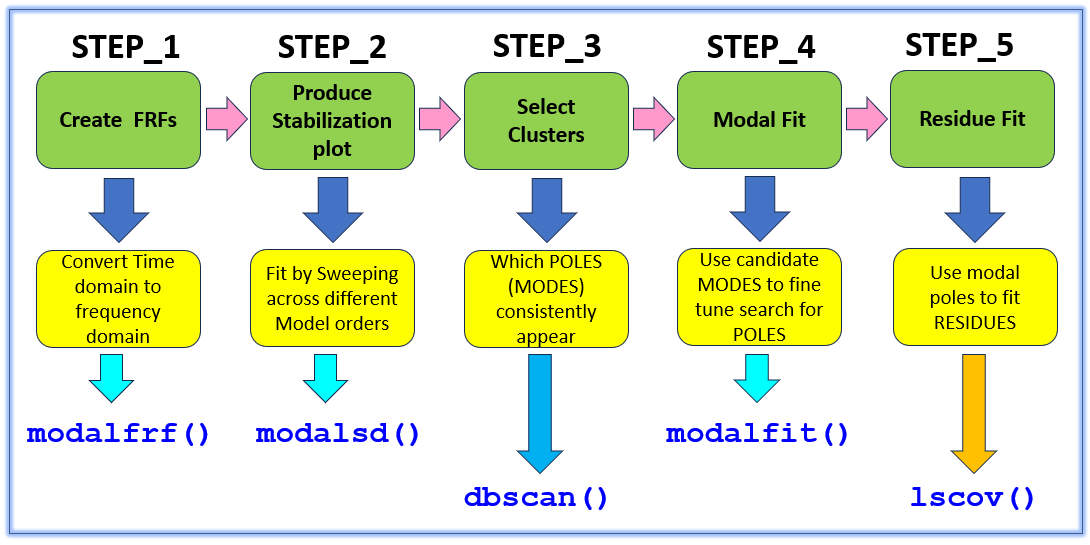

## Clear the workspace

clear

## Load in the FULL Time Series measurement data set

Read the timeseries data from the EXCEL file

MEAS_tab = readtable("bh_RAW_IMPACT_MEAS.xlsx");

So what are the raw column names

MEAS_tab.Properties.VariableNames'

ans = 3×1 cell array
    {'time'}
    {'F'   }
    {'Z'   }


Rename the COLUMNS

MEAS_tab.Properties.VariableNames = ["t","F","Z"];

whos MEAS_tab

  Name              Size             Bytes  Class    Attributes

  MEAS_tab      22001x3             529485  table              




head(MEAS_tab)

      t       F         Z     
    ______    _    ___________

         0    0    -5.5511e-17
    0.0005    0    -5.5511e-17
     0.001    0    -5.5511e-17
    0.0015    0    -5.5511e-17
     0.002    0    -5.5511e-17
    0.0025    0    -5.5511e-17
     0.003    0    -5.5511e-17
    0.0035    0    -5.5511e-17



## Visualize the FULL timeseries Measurements:

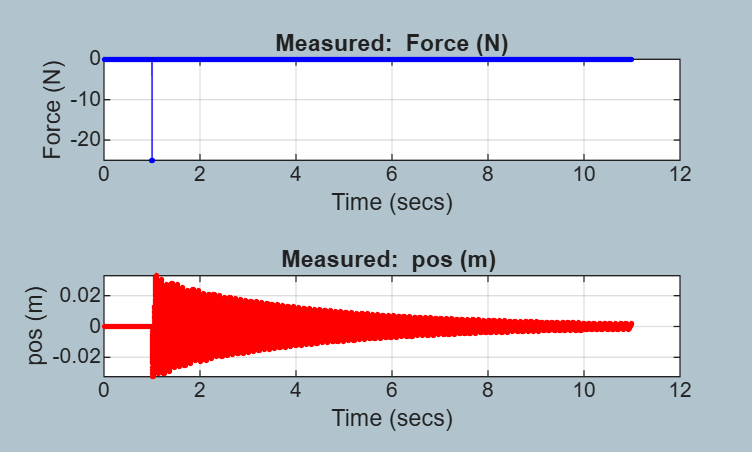

figure;
    tiledlayout(2,1);
    
    hax(1) = nexttile;
        plot(MEAS_tab.t, MEAS_tab.F, '-b.'); grid on; xlabel("Time (secs)"); ylabel("Force (N)");
        title("Measured:  Force (N)");
    
    hax(2) = nexttile;
        plot(MEAS_tab.t, MEAS_tab.Z, '-r.'); grid on; xlabel("Time (secs)"); ylabel("pos (m)");
        title("Measured:  pos (m) ");   
    
    linkaxes(hax,"x") % link axes for ZOOMING

## Set up some Signal processing parameters:

Define the sampling frequency 

Fs_hz     = 1/(MEAS_tab.t(2) - MEAS_tab.t(1))

Fs_hz = 2000

Define window attributes

- The windowing variables will be used by [`modalfrf()`](matlab:  doc modalfrf)

% ATTENTION:  for an IMPACT test use a rectangular window
% THE_WINDOW =  ones( length(MEAS_tab.t), 1 );
% n_OVERLAP  = 0;
%-----------------------------------------------------------
[THE_WINDOW, TAU_window] = bh_create_expon_window(MEAS_tab.t, F_col=MEAS_tab.F);
%THE_WINDOW = ones(size(MEAS_tab.F));
n_OVERLAP  = 0;

Sunlight test:  what will the windowed timeseries data look like?

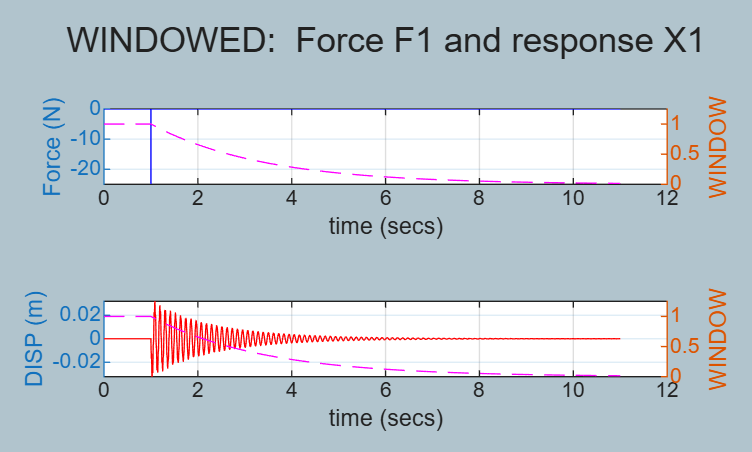

figure
    tiledlayout(2,1)

    nexttile
        yyaxis left
        plot(MEAS_tab.t, THE_WINDOW .* MEAS_tab.F, "-b"); 
            xlabel("time (secs)"); ylabel("Force (N)"); grid on
        yyaxis right
        plot(MEAS_tab.t, THE_WINDOW, "--m"); ylabel("WINDOW"); ylim([0, 1.25])

    nexttile
        yyaxis left
        plot(MEAS_tab.t, THE_WINDOW .* MEAS_tab.Z, "-r"); 
            xlabel("time (secs)"); ylabel("DISP (m)"); grid on
        yyaxis right
        plot(MEAS_tab.t, THE_WINDOW, "--m"); ylabel("WINDOW");  ylim([0, 1.25])

sgtitle("WINDOWED:  Force F1 and response X1")

# **STEP_1:**    Estimate the Systems FRF

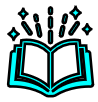 **DOC**:   see [`modalfrf()`](matlab:  doc modalfrf)

[all_frf, all_f, tmp_coh] = modalfrf(MEAS_tab.F, MEAS_tab.Z, ...
                                     Fs_hz, THE_WINDOW, n_OVERLAP, Sensor="dis");


whos  all_frf  all_f

  Name             Size             Bytes  Class     Attributes

  all_f        11001x1              88008  double              
  all_frf      11001x1             176016  double    complex   



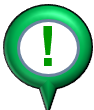 **NOTE:**  the frequency vector `all_f` (in Hz) that is returned only includes frequencies up to the NYQUIST frequency

all_f(end)

ans = 999.9545

## Visualize the MEASURED (estimated) FRF

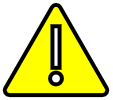 Assert that our FRF variable only has 1 column

assert(1==size(all_frf,2), "###_ERROR:  Hey - we're doing a SISO analysis ... why are there more than 1 FRFs ?");

**Define some data containers for storing these estimated FRFs:**

meas.frf       = all_frf;
meas.coh       = tmp_coh;   % understood will be NaN IFFF only 1 window block used
meas.f_hz      = all_f; 
meas.w         = 2*pi*meas.f_hz;
meas.frf_dB    = 20*log10(abs(meas.frf));
meas.phase_deg = rad2deg(  angle(meas.frf)   );

#### Specify the Frequency range of interest

Let's also select a frequency range of interest that we'll focus on when we eventually do the fitting task(later in this script)

roi.range_Hz = [0, 350];  %[0, 350];  %  [0, 200];

tmp_ind      = find( (meas.f_hz > roi.range_Hz(1)) & (meas.f_hz < roi.range_Hz(2))  );

roi.f_Hz     = meas.f_hz(tmp_ind);
roi.frf      = meas.frf(tmp_ind, :);
roi.coh      = meas.coh(tmp_ind, :);

#### And plot the Measured (estimated) FRFs

Plot every 2nd one to reduce the number of generated plots

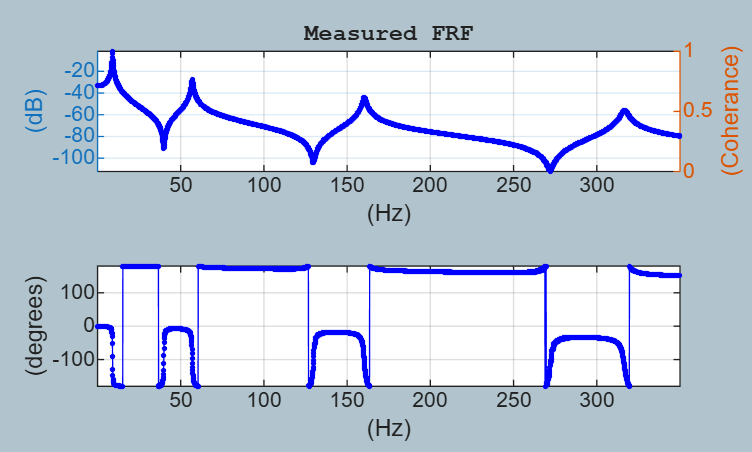

figure;
      hax(1) = subplot(2,1,1); 
       yyaxis left
           plot(roi.f_Hz, 20*log10( abs(roi.frf)), "-b.", "DisplayName","MEAS")
               grid on; axis tight
               xlabel("(Hz)");   ylabel("(dB)");
       yyaxis right
           plot(roi.f_Hz, roi.coh, "-m.", "DisplayName","COH")
               grid on; axis tight
               xlabel("(Hz)");   ylabel("(Coherance)");

               title("Measured FRF", "FontName","Courier", "Interpreter","none")

      hax(2) = subplot(2,1,2); 
           plot(roi.f_Hz, rad2deg( angle(roi.frf) ), "-b.")
               grid on; axis tight
               xlabel("(Hz)");  ylabel("(degrees)")

      linkaxes(hax,"x") % link axes for ZOOMING

# **STEP_2:**    Produce Stabilization plot

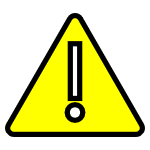 **NOTE:  **for this Cantilever data set .. the LSRF method can be sooooo slow ...So I recommend you do NOT select that.

try_it_FitMethod = "lsce";

### Consider the Stabilization diagram

 **DOC**:   see  [`modalsd()`](matlab:  doc  modalsd)

We'll use ALL of our FRF channels

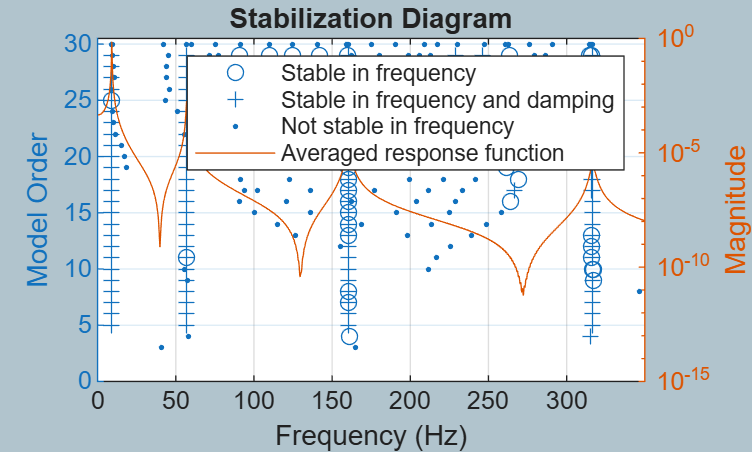

fn_sd =        NaN         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
       NaN       NaN         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
       NaN       NaN       NaN         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
       NaN  160.9389  315.2907       NaN         0         0         0         0         

DESIRED_MAXMODES = 30;

figure   %  the STABILIZATION plot
    fn_sd = modalsd( meas.frf, meas.f_hz, Fs_hz, ...
                     MaxModes=DESIRED_MAXMODES, ...
                     FreqRange=roi.range_Hz, ...
                     FitMethod=try_it_FitMethod)

Maybe we weren't able to sweep across the desired MAX modes

ACTUAL_MAXMODES = size(fn_sd, 2);  

Remove NaNs and ZEROS

FN_HZ_ALL          =   rmmissing(fn_sd(:));
tmp_ind            =  FN_HZ_ALL == 0;
FN_HZ_ALL(tmp_ind) = [];

# **STEP_3:**   Look for Clusters from the Stabilization plot

 REMEMBER: many of the modes will NOT be real modes, rather they will be computational ones that we need to ignore. 

### Select modes based on CLUSTERING and a count threshold

 So let's utilize a data **CLUSTERING** algorithm to semi automate where we think the real modes are.  We will need to tune this, e.g.:  

- the **neighborhood radius** may need some "trial/error" tuning.

- the **minimum number of counts** within a cluster may need some "trial/error" tuning.

See:  [`bh_collect_by_clustering()`](matlab:  open bh_collect_by_clustering)  which simply invokes [`dbscan()`](matlab: doc dbscan) to cluster candidate physical modes

Found 4 candidate modes:
 Mode  1: f = 9.0890 Hz  (count = 26)
 Mode  2: f = 56.9967 Hz  (count = 27)
 Mode  3: f = 160.3650 Hz  (count = 48)
 Mode  4: f = 316.5806 Hz  (count = 48)


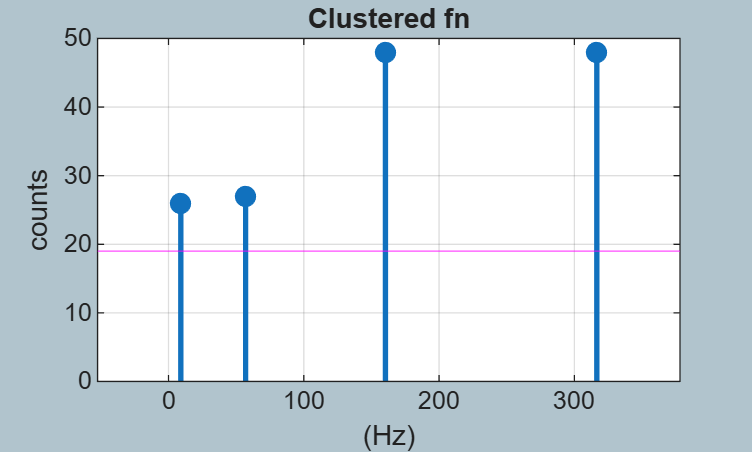

clust_fHz_radius = 1;
clust_min_counts = floor(0.66*ACTUAL_MAXMODES);
clust_fHz_range  = roi.range_Hz;

my_fhz_list_FROM_collect = bh_collect_by_clustering(FN_HZ_ALL, clust_fHz_radius, clust_min_counts, fHz_range=clust_fHz_range);

So our candidate resonant frequencies are:

my_fhz_list_FROM_collect

my_fhz_list_FROM_collect =     9.0890
   56.9967
  160.3650
  316.5806


# **STEP_4:**   Extract our Modal Poles

So from the stabilization diagram, how many modes do you think we should try and fit ?

-  **NOTE:** We'll also specify a HIGHER target number of modes to fit . Overspecifying the number of modes gives better (?) results.

NUM_MODES_TO_FIT = 10

NUM_MODES_TO_FIT = 10

- see DOC for [`modalfit()`](matlab:  doc  modalfit) 

- **NOTE: ** We'll specify the frequencies extracted from our histogram and pass these into [`modalfit()`](matlab:  doc  modalfit) as 'PhysFreq'.  

[fn,dr,ms] = modalfit( meas.frf, meas.f_hz, Fs_hz, ...
                       NUM_MODES_TO_FIT, ...
                       PhysFreq=my_fhz_list_FROM_collect, ...
                       FreqRange=roi.range_Hz, ...
                       FitMethod=try_it_FitMethod);

Remove any Nans:

tmp_ind  = ~isnan(fn) & ~isnan(dr);

fn_clean = fn(tmp_ind);
dr_clean = dr(tmp_ind);

Tabulate these

array2table([fn(:), dr(:)],'VariableNames',{'fn_hz','zeta'})

ans = 4×2 table
    fn_hz       zeta   
    ______    _________

     9.089      0.01233
    56.995    0.0061792
    160.36    0.0054191
    316.54    0.0051063

	Get insights using Copilot


# **STEP_5:**   Extract our Modal RESIDUES

For each FRF

- 
$$\mathrm{FRF}=\;\left(\sum_{k=1}^N \left.\;\;\frac{R_k }{s-\lambda_k }+\;\frac{\bar{R_k } }{s-\bar{\lambda_k } }\right)\;\;\;+\;\;\;\;\;\frac{f}{s^2 }\;\;\;+\;\;\;\;\;\;e\right.$$


Compute the residues for each mode in each FRF.  See the following commentary for some revision on this:

- [`APPENDIX_01_Modal_Model_Representation.mlx`](matlab:  open  bh_Modal.APPENDIX_01_Modal_Model_Representation)

- [`APPENDIX_02_Complex_Residue_Curve_Fit.mlx`](matlab:  open  bh_Modal.APPENDIX_02_Complex_Residue_Curve_Fit)    

Also note that:

- `size(my_R_mat) == NUM_MODES x NUM_RESP_CHANNELS`


[my_R, my_e, my_f]  = bh_Modal.bh_calc_resids_LIVE( fn_clean, ...
                                                    dr_clean, ...
                                                    roi.f_Hz, ...
                                                    roi.frf    )

my_R =   -0.0089 - 0.5891i
  -0.0085 - 0.0937i
  -0.0081 - 0.0321i
  -0.0080 - 0.0154i


my_e = 2.1747e-05 - 8.3330e-06i

my_f = -7.0219e-07 - 4.3016e-07i

#### Visual inspection of Residues

Visually confirm **Residues** have phases close to either 90 degrees OR -90 degrees

- For rationale, see:  [`APPENDIX_01_Modal_Model_Representation.mlx`](matlab:  open  bh_Modal.APPENDIX_01_Modal_Model_Representation)

-  If you see RESIDUE phase angles (absolute value) outside the range $\left\lbrack {70}^o ,{120}^o \right\rbrack$, then you might consider "pruning" these modes out.

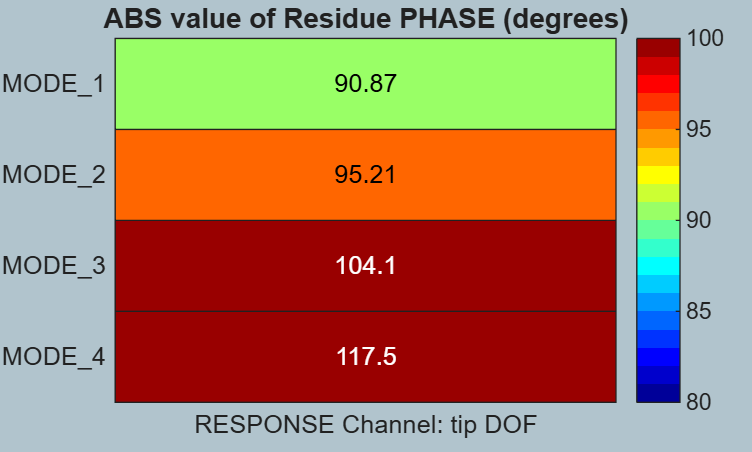

tmp_res_phas_degs = abs( rad2deg(angle(my_R)) );

figure;
    heatmap( tmp_res_phas_degs, "Colormap", jet(20), ...
             YDisplayLabels="MODE_"+(1:height(my_R)), ...
             XDisplayLabels="RESPONSE Channel: tip DOF", ...
             Interpreter="none" );       
        title("ABS value of Residue PHASE (degrees)")
         clim([80 100])

#### Summarize the Identified MODAL properties

fprintf("\n FINAL results ----> ")


 FINAL results ----> 

EMA_RESULTS_tab = array2table([fn_clean(:), dr_clean(:), (2*pi*fn_clean(:))],...
                            'VariableNames',{'fn_Hz','zeta', 'wn_radpersec'});
EMA_RESULTS_tab

EMA_RESULTS_tab = 4×3 table
    fn_Hz       zeta       wn_radpersec
    ______    _________    ____________

     9.089      0.01233       57.108   
    56.995    0.0061792       358.11   
    160.36    0.0054191       1007.6   
    316.54    0.0051063       1988.9   

	Get insights using Copilot


## Compare the Measured FRF against the fitted model

OK - so what do our **fitted** FRFs look like when compared against the **Measured** FRFs ?

fprintf("\n .... PLOT fitted and measured FRFs");


 .... PLOT fitted and measured FRFs

  
my_sdyn_OBJ = bh_Modal.CLS_sdyn_frf(     EMA_RESULTS_tab.zeta, ...
                                    2*pi*EMA_RESULTS_tab.fn_Hz, ...
                                    my_R, my_e, my_f);

So here's a summary of our parametric fitted model:

my_sdyn_OBJ.print()


---------------------------------------------------------------------------
 ID_label = sdt_foo

 mode#      Wn[Hz]       DAMP[-]       Real(R)          Imag(R)        Phase(R)[degs]      
  1          9.089      0.01233       -0.00889529          -0.5891     -90.87  
  2         56.995      0.00618       -0.00854583       -0.0936568     -95.21  
  3        160.363      0.00542       -0.00806482       -0.0321143    -104.10  
  4        316.542      0.00511       -0.00801652       -0.0154278    -117.46  

 E = 2.17469e-05 + i*-8.33299e-06
 F = -7.02189e-07 + i*-4.30164e-07

Let's plot the Model AND the Measured FRFs

my_sdyn_OBJ.s_w_fhz_col = roi.f_Hz;

figure;
  hax(1) = subplot(2,1,1); 
       plot(roi.f_Hz, 20*log10( abs(roi.frf)), "-r.", "DisplayName","MEAS")
           grid on; axis tight
           xlabel("(Hz)");   ylabel("(dB)");
           title("FRF", "Interpreter","none")

  hax(2) = subplot(2,1,2); 
       plot(roi.f_Hz, rad2deg( angle(roi.frf) ), "-r.")
           grid on; axis tight
           xlabel("(Hz)");  ylabel("(degrees)")

hold(hax(1),"on")
    axes(hax(1))
    plot(my_sdyn_OBJ.s_w_fhz_col, my_sdyn_OBJ.db, "-b","DisplayName","fit");

hold(hax(2))

Current plot held


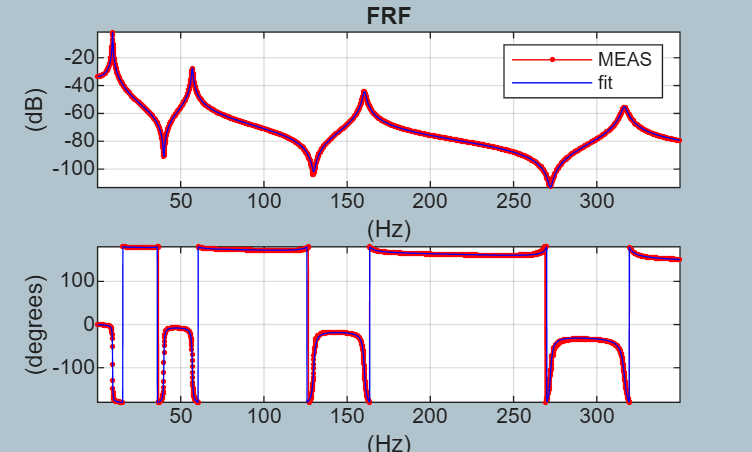

    axes(hax(2))
    plot(my_sdyn_OBJ.s_w_fhz_col, my_sdyn_OBJ.phase("DEGS"), "-b");

legend(hax(1), "Location", "best")

linkaxes(hax, "x")  


    drawnow

#### Plotting:  Part 2 - Plot the model in 3D

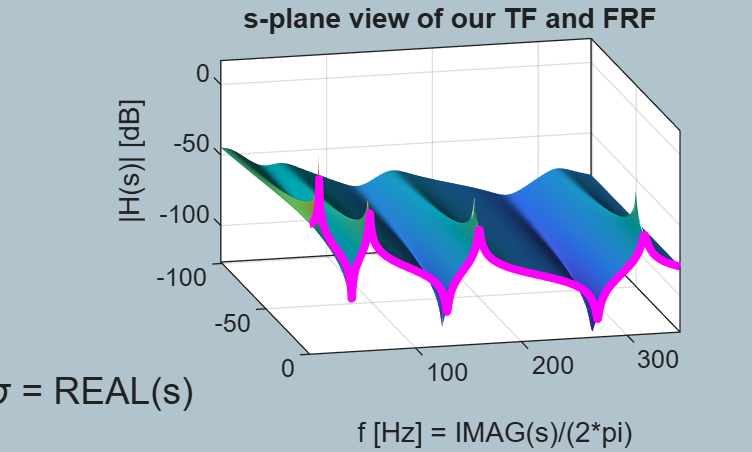

my_sdyn_OBJ.plot_3d_db()

##  Pause and Ponder - Part A

Because we used an EXPONENTIALLY decaying window on the system response, the damping ratios ($\zeta_{\mathrm{FRF}}$) extracted from the FRFs are actually a combination of the ACTUAL modal damping ($\zeta_n$) and the extra damping ($\zeta_{\mathrm{WIN}}$) applied by the exponential window.  Conceptually we have:

- $e^{-\frac{t}{\tau_{\mathrm{WIN}} }} \;\ldotp e^{-\zeta_n \ldotp \omega_n \ldotp t} \;\;\;\;=\;\;\;e^{-\left(\frac{1}{\tau_{\mathrm{WIN}} }\;\;\;+\;\;\;\zeta_n \ldotp \omega_n \right)\ldotp t} \;\;\;\;=\;e^{-\left({\;\zeta }_{\mathrm{WIN}} \;\;\;+\;\;\;\zeta_n \;\right)\ldotp \omega_n \ldotp t}$       where      $\zeta_{\mathrm{WIN}\;\;} =\;\;\frac{1}{\tau_{\mathrm{WIN}} \;\ldotp \omega_n }$

So ? - So IFFF you want the true damping of the structure, you'll need to POST PROCESS the damping ratio extracted from the FRF, via: 

- $\zeta_{n\;} \;\;=\;\;\zeta_{\mathrm{FRF}} \;-\zeta_{\mathrm{WIN}}$       (since:     $\zeta_{\mathrm{FRF}\;} \;\;=\;\;\zeta_{\mathrm{WIN}} \;+\;\zeta_n$  )

zeta_true = EMA_RESULTS_tab.zeta - (  1./(EMA_RESULTS_tab.wn_radpersec * TAU_window)  )

zeta_true =     0.0050
    0.0050
    0.0050
    0.0049


##  Pause and Ponder - Part B

So let's recall the Modal properties extracted from our FRFs.

We're specifically interested in the UNdamped natural frequencies $\omega_n$

EMA_RESULTS_tab

EMA_RESULTS_tab = 4×3 table
    fn_Hz       zeta       wn_radpersec
    ______    _________    ____________

     9.089      0.01233       57.108   
    56.995    0.0061792       358.11   
    160.36    0.0054191       1007.6   
    316.54    0.0051063       1988.9   

	Get insights using Copilot


So how do these compare to the bending modes computed via Engineering Beam theory ? - we'll look at that next.

# Analytic Bending Modes

For a Cantilever beam, the **analytical frequencies** of transverse vibration can be derived and are tabulated in most introductory texts on Mechanical vibrations - e.g.: see

-    Rao, S., "Mechanical Vibrations, 2nd Edition", Addison Wesley, 1990

The first 4 Transverse natural frequencies are:

- See the function [`bh_cantil_analytic_modes()`](matlab:  open  bh_cantil_analytic_modes)

col_OBJ = bh_create_column_OBJ(Width=1/1000, Depth=25.4/1000, Length=300/1000, density=7800);
my_E    = col_OBJ.E_GPa_Young*1e9; % (Pa)
my_I    = col_OBJ.Iy;
my_dens = col_OBJ.density;
my_A    = col_OBJ.WIDTH_x * col_OBJ.DEPTH_y;
my_L    = col_OBJ.LENGTH_z;

ANALYTIC_tab = bh_cantil_analytic_modes(my_A, my_E, my_I, my_L, my_dens);

So what are they ?

display(ANALYTIC_tab)

ANALYTIC_tab = 4×2 table
    fn_Hz     wn_radpersec
    ______    ____________

    9.0888       57.106   
    56.958       357.88   
    159.49       1002.1   
    312.53       1963.7   

	Get insights using Copilot


So how do the EMA extracted modes compare to the analytic Beam Theory modes?

COMPARE_tab = array2table( [ EMA_RESULTS_tab.fn_Hz, ...
                             ANALYTIC_tab.fn_Hz, ...
                             (EMA_RESULTS_tab.fn_Hz ./ ANALYTIC_tab.fn_Hz)], ...
                            'VariableNames',{'fn_Hz(EMA)', 'fn_Hz(ana)', 'RATIO (EM/ana)'})

COMPARE_tab = 4×3 table
    fn_Hz(EMA)    fn_Hz(ana)    RATIO (EM/ana)
    __________    __________    ______________

       9.089        9.0888               1    
      56.995        56.958          1.0006    
      160.36        159.49          1.0055    
      316.54        312.53          1.0128    

	Get insights using Copilot


**Some comments:**

- The first 2 bending models are the most accurate

- The accuracy of the last 2 ,modes can be improved by discretizing the FLEXIBLE beam simulation model with more finite elements (we only used 5 elements in our model)